# UAV Coverage Planning

## Defining the Region

Lat, Long of top right corner, and bottom left corner of the region

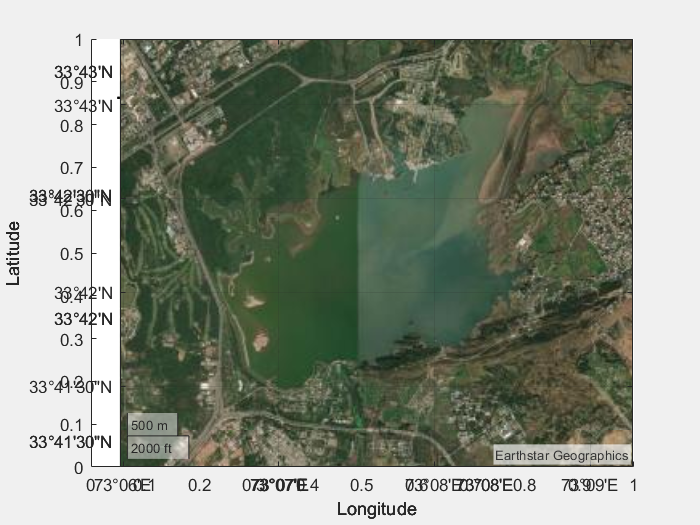

clear
hold off
bottom_right = [33.69682031163671, 73.15458501423868];
top_left = [33.71019668948866, 73.09967815022378];

latmin = min(bottom_right(1), top_left(1));
latmax = max(bottom_right(1), top_left(1));

longmin = min(bottom_right(2), top_left(2));
longmax = max(bottom_right(2), top_left(2));

lat_limits = [latmin, latmax];
long_limits = [longmin, longmax];

geocenter = [mean(lat_limits) mean(long_limits) 0];
gax = geoaxes(Basemap="satellite");
geolimits(lat_limits,long_limits);

## Setting The ROI

You can specify the ROI coordinates in two ways:

- **Import Pre Defined Coordinates**: If you are using the example map, pre-defined ROI coordinates can be imported directly.

- **Draw Coordinates Manually**: If you are using a custom map, it is recommended to manually draw your own ROI to ensure accuracy.

### **Import Pre Defined Coordinates**

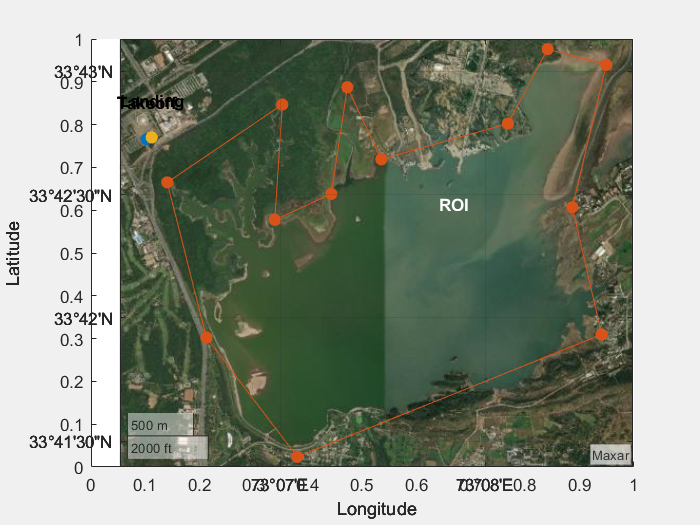

% Load parameters
load parameters.mat

% Plot takeoff position
geoplot(gax, takeoff_lat, takeoff_long, LineWidth=2, MarkerSize=25, LineStyle="none", Marker=".")
text(gax, takeoff_lat + 0.0025, takeoff_long, "Takeoff", HorizontalAlignment="center", FontWeight="bold")

% Hold for additional plots without redrawing axes
hold(gax, "on")

% Plot ROI points
geoplot(gax, roi_points(:,1), roi_points(:,2), MarkerSize=25, Marker=".")
text(gax, mean(roi_points(:,1)), mean(roi_points(:,2)) + 0.006, "ROI", HorizontalAlignment="center", Color="white", FontWeight="bold")

% Plot landing position
geoplot(gax, landing_lat, landing_long, LineWidth=2, MarkerSize=25, LineStyle="none", Marker=".")
text(gax, landing_lat + 0.0025, landing_long, "Landing", HorizontalAlignment="center", FontWeight="bold")

% Turn off hold to allow new plots if needed
hold(gax, "off")

### Draw Coordinates Manually

- **Mark the Takeoff Position**:Begin by clicking on the map to mark the takeoff position.

- **Draw the ROI Boundary**:Define the boundary of the ROI by clicking along the edges of the area you want to designate. When you have completed the boundary, press **Enter**.

- **Mark the Landing Position**:Finally, click to mark the landing position, and press **Enter** to finish.

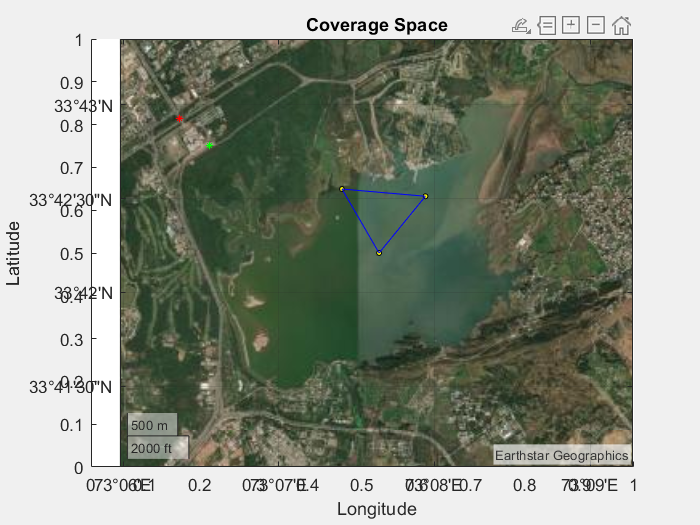

clear takeoff_Lat takeoff_long roi_points xyz land_Lat land_Long
[visLimitsLat,visLimitsLon] = geolimits; 
[takeoff_Lat,takeoff_Long] = TakeoffSelectionFcn(gax,visLimitsLat,visLimitsLon);                                                                                                                              
[roi_points,xyz] = PolygonSelectionFcn(gax,visLimitsLat,visLimitsLon,geocenter);
[land_Lat,land_long] = LandSelectionFcn(gax,visLimitsLat,visLimitsLon);

## Divide ROI into Smaller Regions

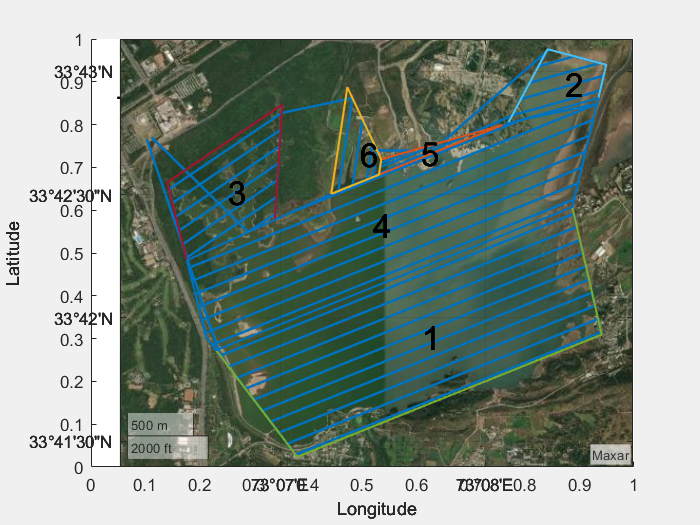

refHeight = 400

subAreasEN = coverageDecomposition(xyz(:,1:2));
subAreasLLA = cell(1,numel(subAreasEN));
refHeight = 400;
for i = 1:1:numel(subAreasEN)
    altitude = refHeight*ones(size(subAreasEN{i},1),1);
    localENU = [subAreasEN{i}(:,1) subAreasEN{i}(:,2) altitude];
    subArea = enu2lla(localENU,geocenter,"flat");
    subAreasLLA{i} = subArea(:,1:2);
end
cs = uavCoverageSpace(Polygons=subAreasLLA, ...
                      UnitWidth=100, ...
                      Sidelap=0, ...
                      ReferenceHeight=refHeight, ...
                      UseLocalCoordinates=false, ...
                      ReferenceLocation=geocenter);
ax = cs.show(Parent=gax,LineWidth=1.25);

## Path Planner

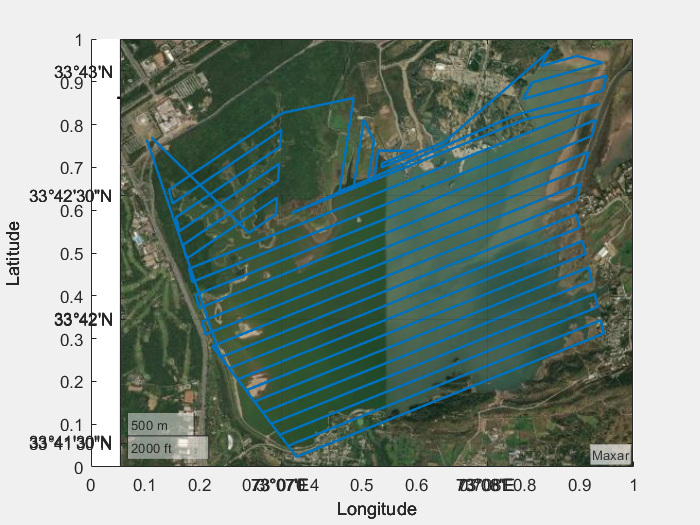

cp = uavCoveragePlanner(cs);
[wpts,solnInfo] = plan(cp,[takeoff_lat takeoff_long 0],[landing_lat landing_long 0]);
path1 = geoplot(gax,wpts(:,1),wpts(:,2),LineWidth=1.5);
hold off

Connecttion_distances_first_path = solnInfo.TransitionCost %cost in meters

Connecttion_distances = 7.5850e+03

## Customing and Optimizing the Survey Path

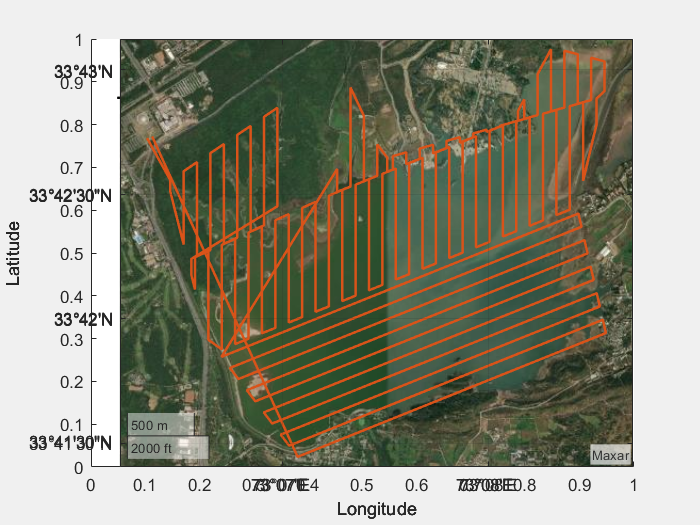

cs.setCoveragePattern(2,SweepAngle=90);
cs.setCoveragePattern(3,SweepAngle=90);
cs.setCoveragePattern(4,SweepAngle=90);
cs.setCoveragePattern(5,SweepAngle=90);
cs.setCoveragePattern(6,SweepAngle=90);
cp.SolverParameters.StartingArea = 3; % set this to whatever region is closest
[wpts,custSoln] = plan(cp,[takeoff_lat takeoff_long 0],[landing_lat landing_long 0]);
delete(path1);
hold on
h2 = geoplot(gax,wpts(:,1),wpts(:,2),LineWidth=1.5);
hold off

Connecttion_distances_optimized_path = custSoln.TransitionCost

Connecttion_distances_optimized_path = 5.9204e+03

## Exporting Waypoints

exportWaypointsPlan(cp,custSoln,"rawalCoverage.waypoints");